# Varmelegeme målinger

T = readtable("varmelegeme_maalinger.xlsx");

## I sekunder

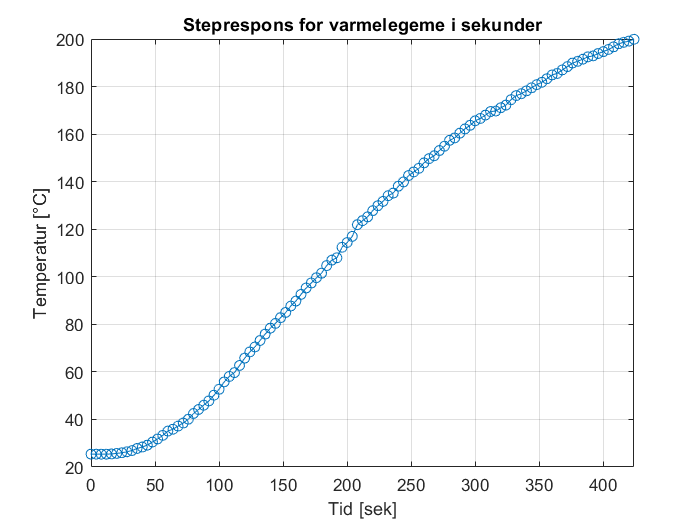

plot(T.Tid,T.Temperatur,'-o')
xlim([0,424]);
title('Steprespons for varmelegeme i sekunder');
xlabel('Tid [sek]');
ylabel('Temperatur [°C]');
grid on;

## I minutter

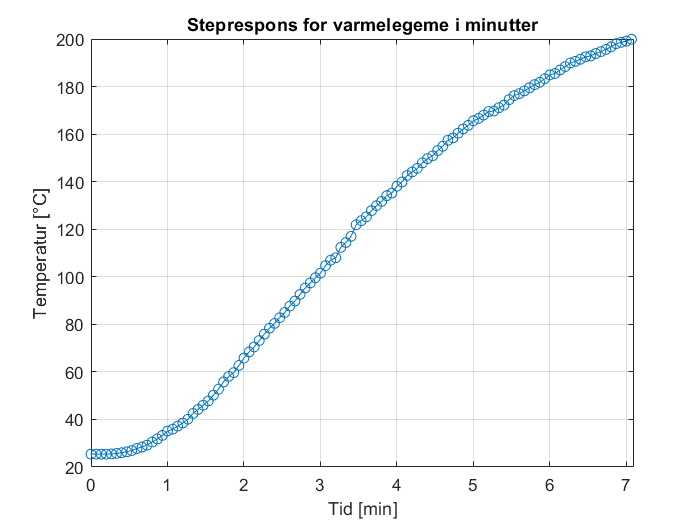

m = T.Tid./60;
plot(m,T.Temperatur,'-o')
xlim([0,7.1]);
title('Steprespons for varmelegeme i minutter');
xlabel('Tid [min]');
ylabel('Temperatur [°C]');
grid on;

## Steady-State

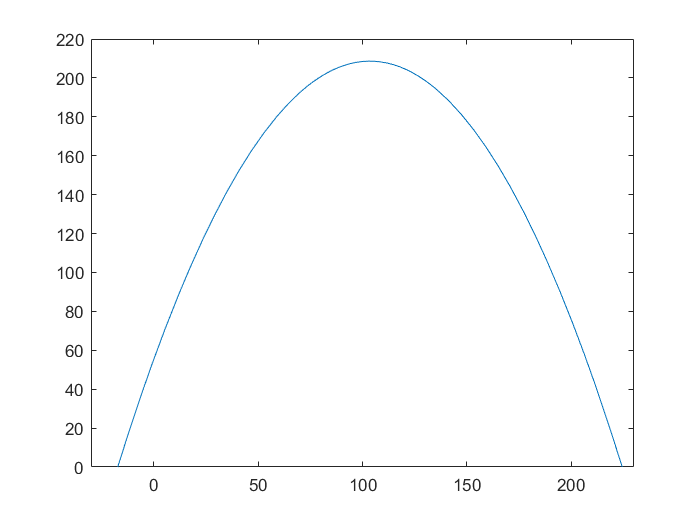

syms x;
y = (-0.0143*x^2)+(2.9623*x)+(55.205); % Tendens fra Excel

fplot(y)
xlim([-30 230])
ylim([0 220])


h = eval(solve(diff(y)== 0));

max = eval(subs(y,x,h))

max = 208.6180